%% load and pick data
close all;
clear;
clc;

pathfig = 'C:\Users\u0130154\MATLAB\projects\seasize\thesis_figure';
pathpng = 'C:\Users\u0130154\OneDrive - KU Leuven\PhD\_writing\_thesis\phdthesis\chapters\actuatordesign\image';

if false
    load gaitdata.mat;
    load actuatordata.mat;
    %keep only sagittal hip data
    TBL = removevars(gaitdata,{'aKsag', 'aAsag', 'mKsag_abs', 'mKsag_max', 'mKsag_min', 'mKsag_rel', 'mKsag_rms', 'pKsag_abs', 'pKsag_max', 'pKsag_min', 'pKsag_rel', 'mAsag_abs', 'mAsag_max', 'mAsag_min', 'mAsag_rel', 'mAsag_rms', 'pAsag_abs', 'pAsag_max', 'pAsag_min', 'pAsag_rel'});
else
    run load_alldata.m
end

% get length and patient identifiers
pat = TBL{:,1};
nr= length(pat);

Tgait = 1.2; %Stride period in seconds
%lowpass filter frequency
flp = 6;
flp_load = 3;
% motor
overload_nom = 1;    % motor nominal overload (increase nominal current rel to nom spec)
overload_pk = 1.96;     % motor peak overload   (increase peak current rel to nom spec)
% gearbox
eff = 1; % efficiency
assistfac = 1;  % ratio of load to assist

load actuatordata.mat
mot_id = 6;
motor_inst = motor(actuatordata(mot_id,:),overload_nom,overload_pk,[]); % select motor

id=31

id = 31

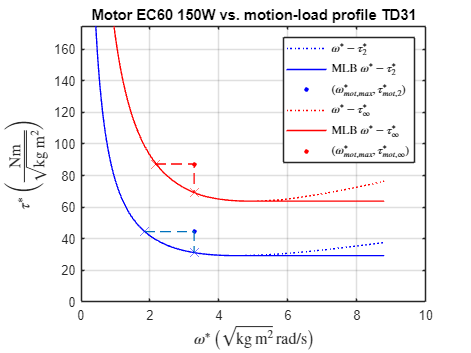

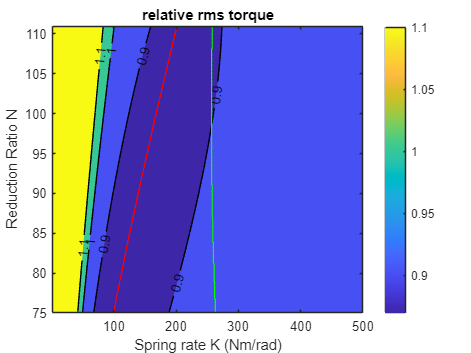

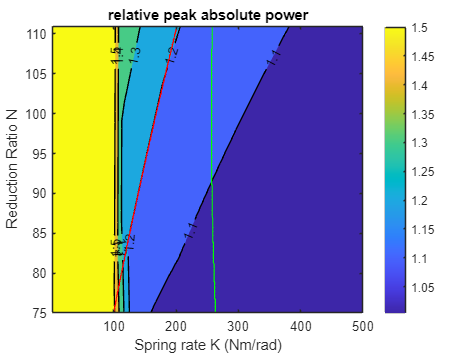

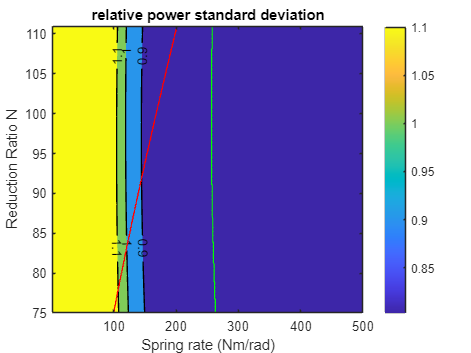


gaitprofile_inst=gaitprofile(char(pat(id)),TBL(id,:),Tgait,assistfac,[],true, 'poslp', flp, 'loadlp', flp_load);
geareval_inst = geareval(motor_inst, gaitprofile_inst,eff,1, 'sea',true);
geareval_inst.eval(300, 300,'Krange',[1,500], 'nNK',[500, 500]);

%geareval_inst.eval(200, 500,'Krange',[1,1000], 'nNK',[200, 1000]);

fig = gaitprofile_inst.plot;
fig.Units = 'inches';
fig.Position = [0, 0, 6, 6.5];
subplot(6,1,6)
legend("Position", [0.58771,0.04605,0.3758,0.033333])
% Save the figure as PNG

savefig([pathfig '\motion_load_TD31' ])
export_fig([pathpng '\motion_load_TD31.png' ], '-png', '-r300', '-nocrop', '-transparent')


fig = figure(geareval_inst.fig)
% Set the figure size
fig.Units = 'inches';
fig.Position = [0, 0, 5, 4];
xlim([0 8])
title('')

annotation("textarrow", [0.5223 0.482], [0.3385 0.2891], "String",  "N="+ string(vpa(geareval_inst.results.maxN,2)))
annotation("textarrow", [0.3631 0.3439], [0.3995 0.3528], "String", "N="+ string(vpa(geareval_inst.results.minNTrms,2)))

annotation("textarrow", [0.4013 0.3673], [0.6197 0.5491], "String", "N=" + string(vpa(geareval_inst.results.minNTmax,2)))

% Save the figure as PNG
% savefig([pathfig '\geareval_TD31' ])
% export_fig([pathpng '\geareval_TD31.png' ], '-png', '-r300', '-nocrop', '-transparent')
%fig = openfig([path '\geareval_unnannotated' ],"new")


fig = figure(geareval_inst.NKfigMrmsContour)
fig.Units = 'inches';
fig.Position = [0, 0, 3.5, 2.5];
title('')
% Save the figure as PNG
savefig([pathfig '\relrmstorque_TD31' ])
export_fig([pathpng '\relrmstorque_TD31.png' ], '-png', '-r300', '-nocrop', '-transparent')

fig = figure(geareval_inst.NKfigPmaxContour)
fig.Units = 'inches';
fig.Position = [0, 0, 3.5, 2.5];
title('')
% Save the figure as PNG
savefig([pathfig '\relpeakpow_TD31' ])
export_fig([pathpng '\relpeakpow_TD31.png' ], '-png', '-r300', '-nocrop', '-transparent')

fig = figure(geareval_inst.NKfigPstdContour)
fig.Units = 'inches';
fig.Position = [0, 0, 3.5, 2.5];
title('')
% Save the figure as PNG
savefig([pathfig '\relstdpow_TD31' ])
export_fig([pathpng '\relstdpow_TD31.png' ], '-png', '-r300', '-nocrop', '-transparent')



%% Select a gearing ratio and stiffness
Nsel=81;
Ksel=200;

[results_sel, figssel]=geareval_inst.plotSelected('N', Nsel, 'K', [50 750 1000]);   % Plots the result for a single N and K as a linspace(50, 1000, 100)
fig = figure(figssel(1))
ylim([0.75 1.2])
fig.Units = 'inches';
fig.Position = [0, 0, 5, 2.8];
legend(Location="northeastoutside")
grid on
title('')
% Save the figure as PNG
savefig([pathfig '\relmetricN81_TD31' ])
export_fig([pathpng '\relmetricN81_TD31.png' ], '-png', '-r300', '-nocrop', '-transparent')


[margs, fig] = geareval_inst.margins(Nsel,'K', Ksel);
fig.Units = 'inches';
fig.Position = [0, 0, 5, 2.8];
legend(Location="northeastoutside")
grid on
title('')
savefig([pathfig '\motlimN81K200_TD31' ])
export_fig([pathpng '\\motlimN81K200_TD31.png' ], '-png', '-r300', '-nocrop', '-transparent')